# Automated Finish Classification for Veridian Lacquer Trend Reports

Veridian Lacquer is a boutic nail polish manufacturer seeking to standardize the classification of nail polish finishes for their anual state of the shade report. Traditionally, finishes such as Creme, Shimmer, Metallic, and Holographic are classified manually, which introduces inconsistency.

The goal of this proect is to develop a machine learning model in MATLAB that automatically classifies nail polish finishes based on measurable color properties: RGB values (Red, Green, Blue), Opacity (0-100), Reflectance Index (0-1). A synthetic dataset is generated to simulate realistic nail polish finish characteristics across four categories : Creme, Shimmer, Metallic, and Holographic. Each class was defined using controlled ranges of RGB values, opacity levels, and reflectance indices to reflect typical visual properties. To ensure consistency and model performance, all numerical features were normalized using standard score normalization, which scales the data to have a mean of zero and a standard deviation of one. This step is particularly important for distance based  algorithm such as k-nearest neighbours (k-NN), ensuring that no single feature dispropotionately influence the classification. On Exploratory data analysis, the scatter plots reveal distinct clustering patterns among the four finish categories. Metallic and Holographic finishes tend to exhibit higher reflective values and on the observation  in this feature space, they are  clearly separable. Creme and Shimmer finishes exhibit some overlap when considering only Red and Reflectance. This indicates that additional features such as Green, Blue, Opacity  are necessary to fully distinguish between these classes. And on the 3D plot since both Metallic and Holographic have high reflectance, overlapping opacity, and RGB differences are not strong enough on the given reflectance range. Reflectance ranges were adjusted  to improve separability between Metallic and Holographic finishes. A slight overlap was intentionally retained to simulate realistic conditions where  similar finishes may share visual properties, ensuring the classification model relies on multiple features rather than a single threshold. 

The dataset  is split into training and testing sets to evaluate how well the model generalizes to unseen data. An 80/20 split is used for this project as is commonly used to balance training performance and evaluation reliability.

**Synthetic Dataset Generation**

% four classes: Creme, Shimmer, Metallic, and Holographic
% features: (RGB values, Opacity percentages, and Light Reflectance Ratios).
% Feature Engineering: Standardize the numerical features 
% Exploratory Data Analysis (EDA) using MATLAB’s gscatter or plot3
% Model Development KNN / Decision tree
% Validation: Split the data into training (80%) and testing (20%) sets.
% Confusion Matrix to visualize the accuracy of the finish predictions.
% save model
% Synthetic data
clc; clear; close all;
% Creating synthetic data
rng(1); % ensure same random data every time

% generate synthetic dataset
n = 150;
%************ Creme Finish *********%
% High opacity, low reflectance, smooth color distribution

R1 = randi([100 255],n,1);
G1= randi([100 255],n,1);
B1 = randi([100 255],n,1);
Opacity1 = randi([80 100],n,1);
Reflect1 = rand(n,1) * 0.3;

% ***********Shimmer Finish *********
% Medium opacity, moderate reflectance, more variation
R2  = randi([80 255],n,1);
G2 = randi([80 255],n,1);
B2 = randi([80 255],n,1);
Opacity2 = randi([50 80],n,1);
Reflect2 = 0.3 + rand(n,1) * 0.3;

% ********** Metalic Finish **********
% High reflectance, moderate opacity
R3 = randi([50 200],n,1);
G3 = randi([50 200],n,1);
B3 = randi([50 200],n,1);
Opacity3 = randi([60 90],n,1);
Reflect3 = 0.6 + rand(n,1) * 0.25;

% *********** Holographic Finish *********
% High reflectance and high RGB variability
R4 = randi([0 255],n,1);
G4 = randi([0 255],n,1);
B4 = randi([0 255],n,1);
Opacity4 = randi([40 80],n,1);
Reflect4 = 0.75 + rand(n,1) * 0.25;

% combine all classes into one dataset
R = [R1; R2; R3; R4];
G = [G1; G2; G3; G4];
B = [B1; B2; B3; B4];
Opacity = [Opacity1; Opacity2; Opacity3; Opacity4];
Reflectance = [Reflect1; Reflect2; Reflect3; Reflect4];

% Create labels

Label = [repmat("Creme", n, 1);
        repmat("Shimmer", n, 1);
        repmat("Metallic", n, 1);
        repmat("Holographic", n,1)];

% Create table

data = table(R,G,B, Opacity, Reflectance, Label);
% display first few rows
disp('Sample of generated dataset');

Sample of generated dataset


tail(data,20);

     R      G      B     Opacity    Reflectance        Label    
    ___    ___    ___    _______    ___________    _____________

      5    176    224      63         0.90266      "Holographic"
    252     14     20      50         0.80323      "Holographic"
    156     41     47      52         0.81244      "Holographic"
     96    183    180      47         0.77804      "Holographic"
      6    248    235      47          0.8269      "Holographic"
     99    237     64      59         0.87436      "Holographic"
    115    230      5      60         0.87245      "Holographic"
    238     32    245      60         0.99889      "Holographic"
     71     37    174      80         0.99528      "Holographic"
    157     18     79      45         0.85914      "Holographic"
    170    138 

summary(data);


data: 600×6 table

Variables:

    R: double
    G: double
    B: double
    Opacity: double
    Reflectance: double
    Label: string

Statistics for applicable variables:

                   NumMissing         Min            Median         Max            Mean            Std    

    R                  0                    1           151           255        149.4583        58.4192  
    G                  0                    3           154           255        149.4850        60.0799  
    B                  0                    0           152           255        149.7150        59.4060  
    Opacity            0                   40            72           100         72.2183        14.7113  


## Feature Engineering

% Feature normalization
% extract numerical features
X = data{:,1:5};

% Normalize data (mean = 0, std = 1)
X_norm = normalize(X);

% extract labels
Y = data.Label;

disp('Feature normalization complete.');

Feature normalization complete.


## Exploratory data analysis

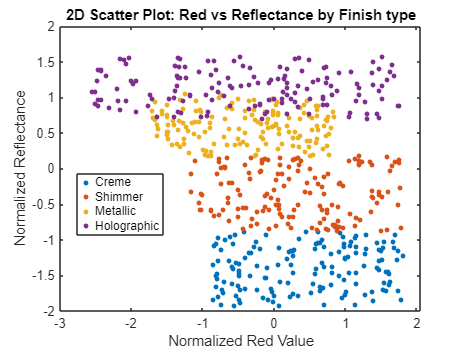

% Visualize relationships between features and class labels
figure
gscatter(X_norm(:,1), X_norm(:,5), Y);
xlabel('Normalized Red Value');
ylabel('Normalized Reflectance');
title('2D Scatter Plot: Red vs Reflectance by Finish type');

## Opacity vs Reflectance

Creme and Shimmer clearly separated, while Metalic and Holographic somehow mixed. So, from feature to feature the separation performance is different.

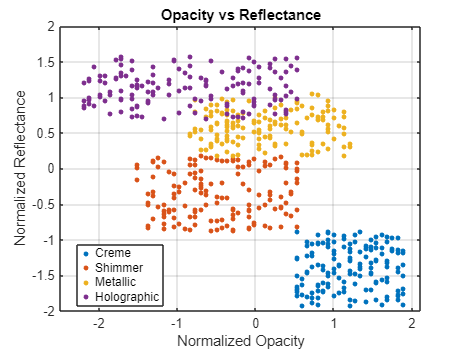

figure
gscatter(X_norm(:,4), X_norm(:,5), Y)
xlabel('Normalized Opacity');
ylabel('Normalized Reflectance');
title('Opacity vs Reflectance');
grid on;

## 3D Scatter Plot

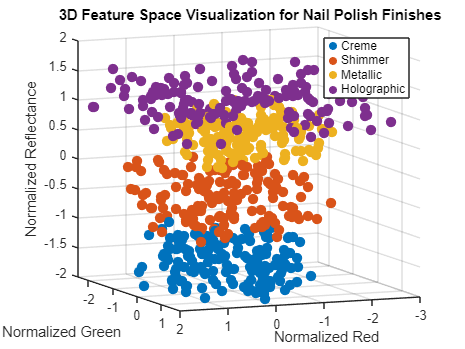

% 3D plot visualization
figure
hold on 

% logical indexing for each class
idx1 = Y == "Creme";
idx2 = Y == "Shimmer";
idx3 = Y == "Metallic";
idx4 = Y == "Holographic";

% Plot each class separately
scatter3(X_norm(idx1,1),X_norm(idx1,2),X_norm(idx1,5), 60, 'filled');
scatter3(X_norm(idx2,1),X_norm(idx2,2),X_norm(idx2,5), 60, 'filled');
scatter3(X_norm(idx3,1),X_norm(idx3,2),X_norm(idx3,5), 60, 'filled');
scatter3(X_norm(idx4,1),X_norm(idx4,2),X_norm(idx4,5), 60, 'filled');

%Labels

xlabel('Normalized Red');
ylabel('Normalized Green');
zlabel('Normalized Reflectance');
title('3D Feature Space Visualization for Nail Polish Finishes');
legend('Creme','Shimmer','Metallic','Holographic');
grid on;
view(157,9)

## Train /Test Split

% Split data into Training and Testing Sets
% We split the dataset into  80% training and 20% testing
cv = cvpartition(Y, 'HoldOut',0.2);
% Training Data
Xtrain = X_norm(training(cv), :);
Ytrain = Y(training(cv));

% Testing data
Xtest = X_norm(test(cv), :);
Ytest = Y(test(cv));

disp('Data split complete:')

Data split complete:


fprintf('Training samples: %d\n', length(Ytrain));

Training samples: 480


fprintf('Testing samples: %d\n', length(Ytest));

Testing samples: 120
